1. Utilizati valorile date mai jos pentru a aproxima $sin(0.34)$utilizand interpolarea Hermite. Dati o delimitare a erorii si comparati-o cu eroarea exacta.

x = [0.3 0.32 0.35];
f = [0.29552 0.31457 0.34290];
df =[0.95534 0.94924 0.93937];

xx = [0.34];
yy = interpolareHermite(x, f, df, xx)

err = 2.7923e-06

yy = 0.3335

err_exact = abs(yy-sin(0.34))

err_exact = 3.7867e-06

yt = exp(xx)

yt = 1.4049

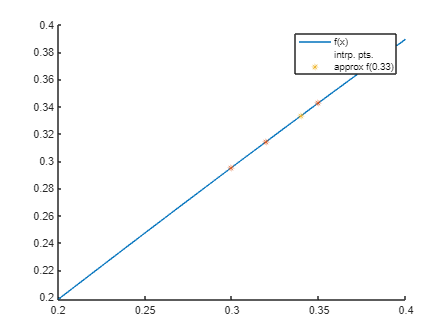


clf
hold on
t = linspace(0.2,0.4);
plot(t, sin(t))
scatter(x,f,'marker','*')
scatter(xx,yy,'marker','*')
legend(["f(x)","intrp. pts.","approx f(0.33)"])
hold off

 Adaugati datele pentru nodul $x=0.33$ si refaceti calculele

x = [0.3 0.32 0.33 0.35];
f = [0.29552 0.31457 sin(0.33) 0.34290];
df =[0.95534 0.94924 cos(0.33) 0.93937];

xx = [0.34];
yy = interpolareHermite(x, f, df, xx)

err = 5.5747e-07

yy = 0.3335

err_exact = abs(yy-sin(0.34))

err_exact = 1.3735e-05

yt = exp(xx)

yt = 1.4049

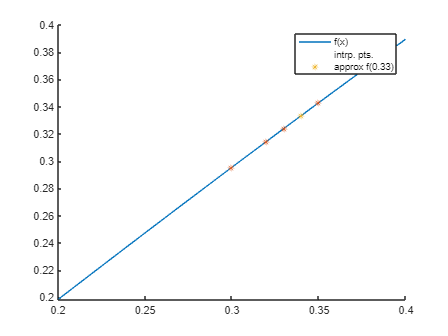


clf
hold on
t = linspace(0.2,0.4);
plot(t, sin(t))
scatter(x,f,'marker','*')
scatter(xx,yy,'marker','*')
legend(["f(x)","intrp. pts.","approx f(0.33)"])
hold off

function [ res ] = interpolareHermite(x, f, fd, point )
% aproximeaza x folosind interpolarea Hermite
    % initializare
    [rows, m] = size(x);
    q = zeros(2 * m + 2, 2 * m + 2);
    z = zeros(2 * m + 2);
    
    % z contine x0 x0 x1 x1 x2 x2 ...
    % Q contine f(x0) f(x0) f(x1) x(x1) ...
    %           - f'(x0) f[x1,x0] f'(x1) f[x2,x1] ...
    for i = 1 : m
        % p2
        z(2 * i - 1) = x(i);
        z(2 * i) = x(i);
        q(2 * i - 1, 1) = f(i);
        q(2 * i, 1) = f(i);
        q(2 * i, 2) = fd(i);
        % p3
        if i ~= 1
            q(2*i-1,2)=(q(2*i-1,1)-q(2*i-2,1))/(z(2*i-1)-z(2*i-2));
        end
    end
    
    % se completeaza diferentele divizate
    for i = 3 : 2 * m
       for j = 3 : i
          q(i,j)=(q(i,j-1)-q(i-1,j-1))/(z(i)-z(i-j+1)); 
       end
    end
        
    % calc p(i)
    n = size(point, 2);
    s = ones(1,n) * 1;
    p = ones(1,n) * q(1, 1);
    for i = 2 : 2 * m
       a = abs(x(floor(i/2)) - point);       
       s = s .* a;
       prev = p;
       p = p + s .* q(i,i);
       res = p;       
       err = abs(prev-p);
       if err<1e-5
          break 
       end
    end
    err
end
